# AERO40003 Computing and Numerical Methods 1 

# Part 2: Numerical Methods 

# **Coursework 2022-2023**

## Dr. Roderick Lubbock

## Completing this live file

You will submit only this self-contained completed livefile.No other scripts or other files will be marked. When completing this livefile:

- Please make sure all of your code is formatted as code using the "code" button on the Live Editor ribbon;

- Please make sure anything that is not code or code comments is formatted as text;

- Marks for each section and sub-section are shown in bold square brackets;

- Ensure that the entire livefile runs without errors or warnings before submitting!

#### Code

All code you write **must have a comment clearly explaining what each line does**. Comments should be brief but clear.

All local functions must:

- be entered in the **Functions** section at the bottom of this livefile;

- be named correctly according to the guidance below;

- have a comment on each line of code explaining its function and **how it relates to the equations in the handouts or other theory;**

- NOT call built-in MATLAB functions from outside the standard MATLAB toolbox `C:\Program Files\MATLAB\R2022b``\toolbox\matlab` (but you may use these to check your functions).

To check the toolbox of a MATLAB function use the which command. The short name of the toolbox is shown after "**toolbox\**"  For example:

returns `C:\Program Files\MATLAB\R2022b\toolbox\``matlab``\polyfun\spline.m` which means it is in the standard MATLAB toolbox, whereas

returns `C:\Program Files\MATLAB\R2022b\toolbox\``curvefit``\curvefit\fit.m` which means it is in the curvefit toolbox, and not the standard MATLAB toolbox.

#### Plots

You should ensure any plots you are asked to produce have:

- axis labels;

- x and y grid;

- all lines/markers clearly differentiable through use of colour or line/marker type;

- legend (where more than one dataset is plotted), placed so as to minimise overlap with data lines/markes;

- any spaced discrete point data (such as that in the table below) plotted as points (not lines);

- when plotting overlapping functions use solid, dashed, chain-dashed and dotted linetypes to maximise visibility of all lines.

Note that any plots that are not formatted as above (and exemplified in the Computer Labs Code livefiles) **will not be marked.**

#### Numerical outputs

Anywhere you are asked to output values you should:

- Use one of the appropriate built-in MATLAB functions e.g. `sprintf` (as in the Computer Lab Codes);

- Include a clear description of what the output variable represents;

- Relative errors should be presented to 2 d.p.

### Submission

- You should submit your livefile on Blackboard by **Friday 24th March 2023 at 1700.**

- Please rename the file in the format **NM1_CW_XXXXXX.mlx where XXXXXX is your CID number.**

- As usual, please ensure you receive a confirmation email following submission. Only confirmed submitted files will be marked (partially complete Blackboard submissions will be ignored).

## Introduction

*Bessel functions* describe electric fields, mechanical vibrations, heat conduction, optical diffraction and other phenomena involving cylindrical or spherical symmetry, for example the displacement of vibrating circular membranes, such as pressure transducer sensing elements and drum skins, as well as temperature distributions in heated cylindrical objects, such as combustor temperature probes and hot dogs in boiling water.  The image below (source:  [https://commons.wikimedia.org/wiki/File:Vibrating_drum_Bessel_function.gif](https://commons.wikimedia.org/wiki/File:Vibrating_drum_Bessel_function.gif) ) shows an animation of a vibrating drum skin. Everything you could possibly want to know about Bessel functions can be found at the [DLMF: NIST Digital Library of Mathematical Functions](https://dlmf.nist.gov/), which is based on a [famous mathemtical handbook](https://www.nist.gov/mathematics-statistics/handbook-mathematical-functions-abramowitz-and-stegun) known as "Abramowitz and Stegun", [available as a pdf here](https://s3.amazonaws.com/nrbook.com/AandS-a4-v1-2.pdf).

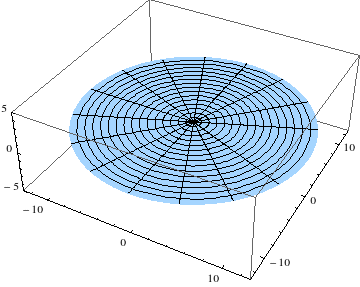

There are various different *kinds* of Bessel functions, including the *first kind *$J_n \left(x\right)$, the *second kind *$Y_n \left(x\right)$ and the *third kind *$H_n \left(x\right)$. For each kind there are also different orders, e.g. integers $n=0,1,2,3\ldotp \ldotp \ldotp$ The Bessel functions of the first kind for the first five integer orders (n = 0 to 4) are plotted below, using the built-in MATLAB function `besselj`. They look a bit like decaying sinusoids, except for some subtle differences as we shall see. 

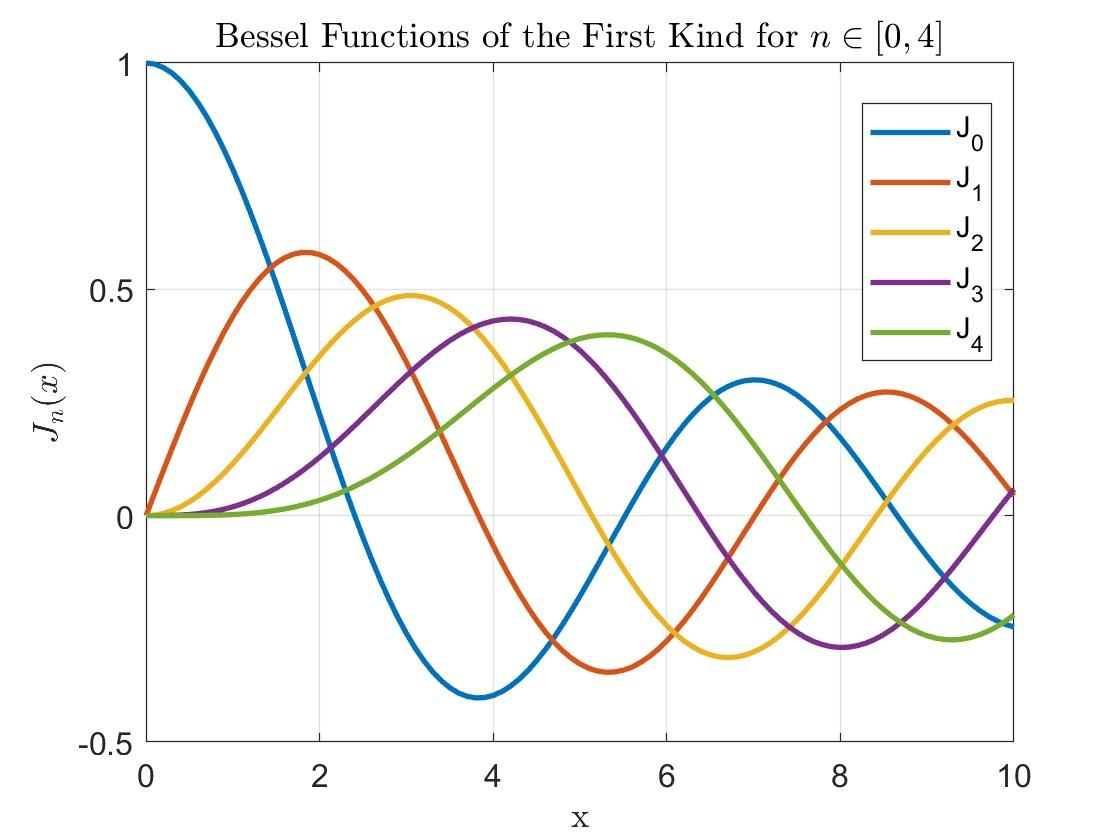

To see how this plot was made run the folllowing code:

Interestingly, the vertical displacement of the drumskin above is given by $u\left(r,\theta \right)=J_3 \left(r\right)\sin \left(3\theta \right)$ in polar coordinates. You should be able to see that, at a certain moment in time (e.g. at the limits of the motion), the vertical displacement plotted in the radial direction resembles $J_3$ in the plot above. You will learn how to obtain the full analytic solution to this sort of time-dependent differential equation later on in the undergraduate course.

**In this coursework you are going to investigate Bessel functions of the first kind, **$J_n \left(x\right)$**, over the interval **$0\le x \le 10$**.**

## Part 1: Interpolation [9 marks]

Bessel functions are usually not amenable to straightforward evaluation (e.g. by hand or with a standard scientific calculator) and are often compiled in standard mathematical tables. One such table is shown below:

BesselTable= array2table([...
  0             0
0.5       0.24227
  1       0.44005
1.5       0.55794
  2       0.57672
2.5       0.49709
  3       0.33906
3.5       0.13738
  4     -0.066043
4.5      -0.23106
  5      -0.32758
5.5      -0.34144
  6      -0.27668
6.5      -0.15384
  7    -0.0046828
7.5       0.13525
  8       0.23464
8.5       0.27312
  9       0.24531
9.5       0.16126
 10      0.043473...
     ], "VariableNames",["x","J"])

BesselTable = 21×2 table
     x         J     
    ___    __________

      0             0
    0.5       0.24227
      1       0.44005
    1.5       0.55794
      2       0.57672
    2.5       0.49709
      3       0.33906
    3.5       0.13738
      4     -0.066043
    4.5      -0.23106
      5      -0.32758
    5.5      -0.34144
      6      -0.27668
    6.5      -0.15384
      7    -0.0046828
    7.5       0.13525


Investigate the different methods of interpolation covered in the course using the interpolant data in the above table as follows:

- **M1.1:** Write a local MATLAB function **called IntPoly** that fits a polynomial of the maximum possible order to the tabular data using the first approach in Handout 4 involving inversion of a matrix of $x$-values. **[1]**

- **M1.2:** Write a local MATLAB function **called LagrangePoly** to compute the interpolating Lagrange polynomial that passes through all inerpolant data points. HINT: You may find the matlab functions `poly` and `polyval` useful.  **[2]**

- **M1.3:** Write a local MATLAB function **called IntSpline** that performs cubic spline interpolation with natural (free-runout) end conditions. **[1]**

All functions should:

- take as input a vector of query points that is evenly spread across the interval and spaced by 0.1

- output the evaluation of the interpolation function at the query points.

Evaluate the performance of your local functions as follows: **[1]**

- **E1.1:** Plot the interpolated data (as a continuous curve) alongside the tabular data (as points) for all methods on a single plot.

- **E1.2:** Evaluate and plot the relative error in the interpolation compared to `besselj`. Plot the relative error as a function of $x$ for all methods on a single plot.

- **E1.3:** Compute and output the time required to perform the interpolation along with the $L_2$-norm of the relative error across the interval using e.g. `sprintf` (as in the Computer Lab Codes) to clearly state which values relate to which method. 

### Questions

- **Q1.1:** How does the performance of the various methods compare in terms of accuracy and computation time? **[1]**

- **Q1.2:** Methods 1. and 2. should generate equivalent polynomials according to Handout 4. Do they?  Try to explain any discrepancies. **[1]**

- **Q1.3:** What happens to the overall error ($L_2$-norm) in method 2 if, instead of using the tabular data, you interpolate data sampled directly from `besselj `with the same number of points (i.e. 21) but using Chebyshev spacing? **[1]**

- **Q1.4:** Compare method 3. with the built-in MATLAB function `spline`. Are the outputs the same? Try to explain any discrepancies. **[1]**

### Hints

**Method M1.2:** One way to approach this is to use a loop to step through the $x_i$ and for each one create a matrix of basis polynomial coefficients, using the built-in MATLAB function `poly` to find the coefficients of the (basis) polynomial whose roots are all the $x_i$ except one. You can then multiply this by a vector of $y_i$ in order to obtain the scaled basis polynomials, and then use built-in MATLAB function `polyval` to evaluate the resulting polynomial coefficients for the query points.

### Part 1: Your Solution

BesselTable= array2table([...
  0             0
0.5       0.24227
  1       0.44005
1.5       0.55794
  2       0.57672
2.5       0.49709
  3       0.33906
3.5       0.13738
  4     -0.066043
4.5      -0.23106
  5      -0.32758
5.5      -0.34144
  6      -0.27668
6.5      -0.15384
  7    -0.0046828
7.5       0.13525
  8       0.23464
8.5       0.27312
  9       0.24531
9.5       0.16126
 10      0.043473...
     ], "VariableNames",["x","J"])

BesselTable = 21×2 table
     x         J     
    ___    __________

      0             0
    0.5       0.24227
      1       0.44005
    1.5       0.55794
      2       0.57672
    2.5       0.49709
      3       0.33906
    3.5       0.13738
      4     -0.066043
    4.5      -0.23106
      5      -0.32758
    5.5      -0.34144
      6      -0.27668
    6.5      -0.15384
      7    -0.0046828
    7.5       0.13525


%E1.1 Interpolated and tabular data plots

%Converts tabular data into an array so it can be plot
BesselArray = table2array(BesselTable);

%Creates x vector of 100 equidistant points to plot interpolated fits
x = linspace(0,10,100);

%Use tic to start timer for evaluating computational time
tic
%Defines y coordinate points in variable 'yinter' from the Interpoly function
yinter = polyval(Intpoly(table2array(BesselTable)),x);

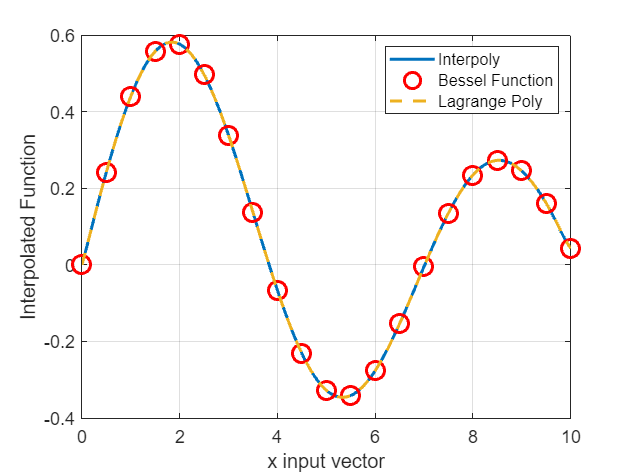

%Use toc to end timer and save time in variable 'intpolytime'
intpolytime = toc;

%Start timer
tic
%Defines y coordinate points in varible 'lagrange' from LagrangePoly function
lagrange = LagrangePoly(table2array(BesselTable),x);
%Stop timer and save time in variable 'lagrangetime'
lagrangetime = toc;

%Plot interpoly function
plot(x,yinter);
hold on;
%Plot tabular data
plot(BesselArray(:,1), BesselArray(:,2),'o','color','red');
hold on
%Plot lagrange polynomial
plot(x,lagrange,'--')
%Create x and y axis labels
xlabel('x input vector')
ylabel('Interpolated Function')
%Create legend
legend('Interpoly','Bessel Function', 'Lagrange Poly')
%Add grid to plot
grid on
hold off

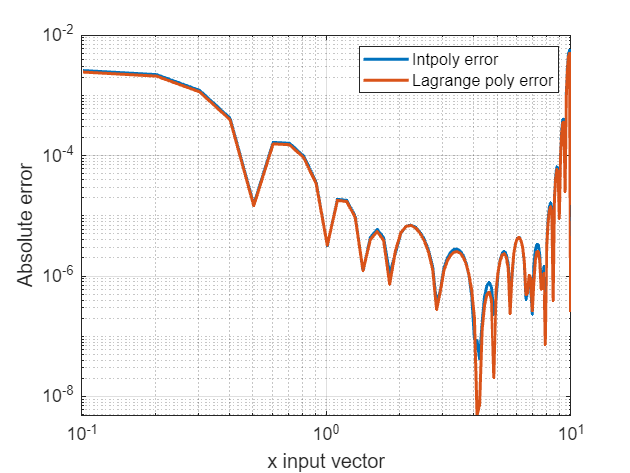

%Evaluate bessel function using inbuilt matlab function
bessel = besselj(1,x);

%Calculate absolute error in intpoly
errorIntpoly = abs(yinter-bessel);
%Calculate absolute error in lagrange polynomial
errorlagrange = abs(lagrange-bessel);

%Create new figure for error plots
figure;
%Using a logarithmic scale plot
%Plotting error in intpoly
loglog(x,errorIntpoly);
hold on
%Plotting error in lagrange polynomial
loglog(x,errorlagrange);
%Adding a legend
legend('Intpoly error','Lagrange poly error')
%Adding axis labels
xlabel('x input vector');
ylabel('Absolute error');
%Adding grid
grid on
hold off

%Calculating L2 norm for intpoly
normIntpoly = norm(x-errorIntpoly,2);
%Calculating L2 norm for lagrange poly
normlagrange = norm(x-errorlagrange,2);
sprintf('Intpoly took %d s to compute and had an L2 norm value of %d',intpolytime,normIntpoly)

ans = 'Intpoly took 9.278500e-03 s to compute and had an L2 norm value of 5.787798e+01'

sprintf('Lagrange polynomial took %d s to compute and had an L2 norm value of %d',lagrangetime,normlagrange)

ans = 'Lagrange polynomial took 1.790590e-02 s to compute and had an L2 norm value of 5.787825e+01'

Q1.1: The fastest method for interpolation is using an inversion of matrix to fit a maximum order polynomial as this took 1.31s to compute compared to the lagrange polynomial which took 1.69s to compute. However, the lagrange polynomial is more accuate as the absoute error graph suggests lower errors.

Q1.2: Methods 1 and 2 produce similar polynomials to the handouts. However, rounding off errors during computation may not produce identical polynomials. The handouts produce continous functions of x whereas Matlab code only approximates these functions using an input vector. This means that the polynomials are not identical.

## Part 2: Numerical Integration [8 marks]

For integer values of $n$, the bessel function of the first kind may be defined in integral form using *Bessel's integrals* as:


$$J_n(x) = \frac{1}{\pi} \int_0^\pi \cos(n\tau-x\sin\tau)d\tau$$


Investigate the different methods of numerical integration covered in the course to evaluate Bessel's integral for the **first order** Bessel Function of the first kind, $J_1 \left(x\right)$ as follows:

- **M2.1:** Write a local MATLAB function **called trapzJ1** that uses the Trapezium rule. **[1]**

- **M2.2:** Write a local MATLAB function** called simpsonJ1** that uses Simpson's 1/3 rule. **[1]**

- **M2.3:** Write a local MATLAB function **called gaussJ1** that uses Gauss-Legendre quadrature. **[3]**

All functions should: 

- take as input a vector $x$ that is evenly spread across the interval and spaced by 0.1, as well as the number of points used in the integration, *N*.

- output $J_1 \left(x\right)$. 

You should evaluate the performance of your local functions as follows **[2]**:

- **E2.1:** Plot the approximated function alongside values computed using `besselj` for all methods on a single plot.

- **E2.2:** Evaluate and plot the relative error compared to `besselj `as a function of $x$ for all methods on a single plot.

- **E2.3:** On a single figure, plot the $L_2$-norm of the relative error across the interval vs the number of points, *N*, used in the integration for each method for a sensible range of *N*. Plot a horizontal line representing double-precision accuracy, and for each method work out how many points are required to evaluate $J_1 \left(x\right)$ to within machine (double) precision of `besselj`.

- **E2.4:** Write a simple loop to evaluate the integral for the vector $x$ using the built-in MATLAB function `integral. `Plot the error across the interval and evaluate the computation time required to achieve double-precision accuracy. 

### Questions

- **Q2.1:**  How does the computation time of the three methods M2.1,M2.2, M2.3 and the looped `integral `function compare? Do you think the function `besselj` uses numerical integration to evaluate Bessel functions? **[1]**

### Hints

**Method M2.1**: Use the built-in MATLAB function` trapz`.

**Method M2.2:** Use an anonymous function (as in the Computer Lab Codes), that takes x and tau as the inputs, in order to define the integrand.

**Method M2.3**: You will need to evaluate the Legendre polynomials to higher orders than in the Class Handouts. 

One way to approach this is to use the MATLAB functions conv and polyder to evaluate the definition of$L_N \left(x\right)$ in Handout 3:


$$L_N(x) =\frac{1}{2^NN!} \frac{d^N}{dx^N}(x^2-1)^N$$


The $(x^2-1)^N$term can be evaluated using the built-in MATLAB function `conv,` which multiplies two polynomials and returns the coefficients of the resulting polynomial (a process known as convolution):

The coefficients of the derivative of a polynomial can be found using built-in MATLAB function `polyder`. You will need to code a loop similar to the one for `conv` to calculate the *N*th derivative. Yo can also use `polyder` and `polyval` to evaluate the weights.

To obtain the roots of the polynomial based on the coefficient simply use the built-in MATLAB function `roots`. To evaluate a polynomial for a given vector of input values simply use the built-in MATLAB function `polyval`.

Another way to generate the Legendre polynomials is using Bonnet's recursion formula:


$$(N+1)L_{N+1}(x) = (2N+1)xL_N(x)-NL_{N-1}(x)$$


Starting with $L_0 \left(x\right)=1$ and $L_1 \left(x\right)=x$ this allows all subsequent polynomials to be computed. For example, $L_2 \left(x\right)$ is found from:

$L_2(x) =\frac{1}{2} \left(3xL_1(x)-L_0(x)\right) = \frac{1}{2} \left(3x^2-1\right) $.

Based on this it is possible to code a recurrence relation to calculate the ceofficients of any Legendre polynomial. To illustrate this consider the coefficients of the first few polynomials:


$$L_0(x) = 1: $$



$$L_1(x)=x:$$



$$L_2(x) = \frac{1}{2} \left(3x^2-1\right) :$$


You should be able to spot a pattern forming that corresponds to Bonnet's recursion formula. Obviously you will need to use a loop and work out how to increment the number of coefficients for each iteration. You can check your polynomials against the symbolic math toolbox function `legendreP.`

### Part 2: Your Solution

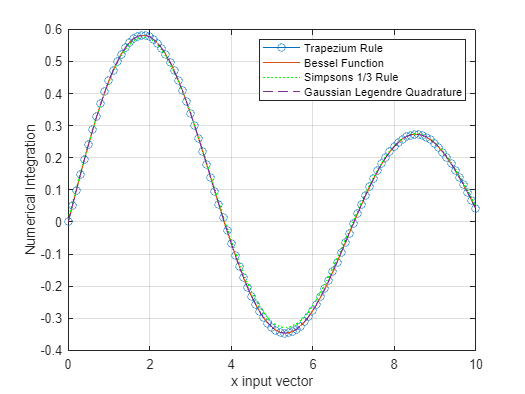

%Creating evenly spaced input x vector across the interval [0 10] with a spacing
%of 0.1
x= 0:0.1:10;

%Defining 'N' number of points used in integration.
N=40;

%Variable trap stores numerial integration values from function trapzJ1
trap = trapzJ1(x,N);
%Variable simpsons stores numerical integration values from function
%simpsonJ1
simpsons = simpsonJ1(x,N);
%Variable gauss storess numerical integration values from function gaussJ1
gauss = gaussJ1(x,N);
%Variable bess stores values evaluated using 'besselj' function
bess = besselj(1,x);
%Creates new figure
figure;

%Plots trap against x
plot(x,trap,'-o')
hold on
%Plots  bess against x
plot(x,bess)
hold on
%Plots simpsons against x
plot(x,simpsons,':','color',[0 1 0])
hold on
%Plots gauss against x
plot(x,gauss,'--');

%Adding legend
legend('Trapezium Rule','Bessel Function','Simpsons 1/3 Rule','Gaussian Legendre Quadrature');
%Adding grid
grid on
%Adding x and y labels
xlabel('x input vector')
ylabel('Numerical Integration')
hold off

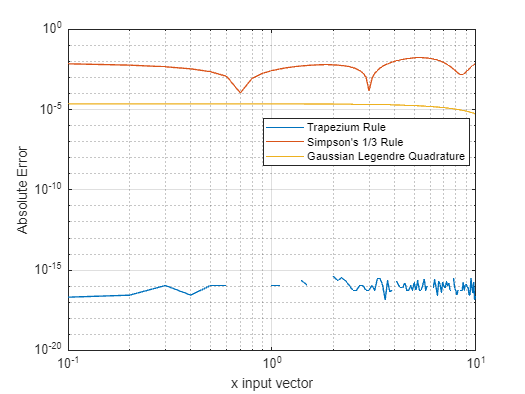

%Calculating absolute error in trapezium rule
errortrap = abs(trap-bess);
%Calculating absolute error in simpsons rule
errorsimpsons = abs(simpsons-bess);
%Calculating absolute error in Gaussian Legendre Quadrature
errorgauss = abs(gauss-bess);

%Creating new figure for error plots
figure;
%Creating logarithmic scale plot for trapezium rule error
loglog(x,errortrap)
hold on
%Creating logarithmic scale plot for simpson's rule
loglog(x,errorsimpsons);
hold on
%Creating logarithmic scale plot for gaussian legendre quadrature 
loglog(x,errorgauss);

%Adding axis labels
ylabel('Absolute Error');
xlabel('x input vector');
%Adding legend
legend('Trapezium Rule',"Simpson's 1/3 Rule",'Gaussian Legendre Quadrature');
%Adding grid
grid on;
%Moving legend so it does not cover data
legend("Position", [0.50557,0.58303,0.38536,0.11476]);
hold off

Enter explanation here.

## Part 3: Function Roots [8 marks]

Compare the various root finding methods that are amenable to this function, without knowing its derivative, to find all roots on the interval. Compare with sine and cosine. Compare with fzero.

Investigate the different methods of root finding covered in the course to find all of the roots on the interval for the **zeroth order** Bessel function of the first kind, $J_0 \left(x\right)$, as follows:

- **M3.1:** Write a local MATLAB function **called fzeroJ** that uses the built-in MATLAB function `fzero`. **[1]**

- **M3.2:** Write a local MATLAB function **called bisectionJ** that uses the bisection method. **[1]**

- **M3.3: **Write a local MATLAB function **called newtonJ** that uses Newton's method. **[1]**

- **M3.4: **Write a local MATLAB function **called secantJ** that uses the Secant method. **[1]**

All functions should: 

- take as input the order of the Bessel function and the start and end points of the interval (i.e. [0 10]).

- output the roots to a tolerance of** 1e-6** (in other words stop iterating when the solution is changing by less than the tolerance), if this is possible within a computation time of say 10 minutes (use Ctrl+C or Command+. to stop the computation if not).

- NOT use predetermined search intervals, but rather determine these from the function itself (so that in principle your code would function for any order/kind of Bessel function and/or outside the interval). 

- all use the same method for determining the search interval.

You should evaluate the performance of your local functions as follows: **[1]**

- **E3.1:** Plot the approximated roots alongside the function evaluated using `besselj`, using a different plot for each method.

- **E3.2:** Compute and output the time required to compute all roots on the interval using e.g. `sprintf` (as in the Computer Lab Codes) to clearly state which values relate to which method. 

### Questions

- **Q3.1:** How do the various methods compare in terms of accuracy and computation time? **[1]**

- **Q3.2:** Are your roots to within machine precision of the true values on page 409 of [Abramowitz and Stegun](https://s3.amazonaws.com/nrbook.com/AandS-a4-v1-2.pdf)? If not, why not? **[1]**

- **Q3.3:** Does your function work for other orders of the Bessel function of the first kind, $J_0 \left(x\right)$, and/or for roots outside the interval (i.e. $x>10$)? If so, when does it stop working and why? How would you need to modify your code to get it to work? N.B. you should not try to modify your function to get it to work on other functions or outside the interval, as this problem is hard enough already, but you should only try to understand (and explain) why it doesn't work. **[1]**

### Hints

One way to find the search interval is to start from the origin and find the first data point where the sign has changed, then search between that point and the next. You can then continue this to the next root. 

**Method 3.3:** You will need to work out the derivative. This can be found from the series definition of the function, and you can also look it up at [DLMF: §10.6 Recurrence Relations and Derivatives ‣ Bessel and Hankel Functions ‣ Chapter 10 Bessel Functions (nist.gov)](https://dlmf.nist.gov/10.6).

### Part 3: Your Solution

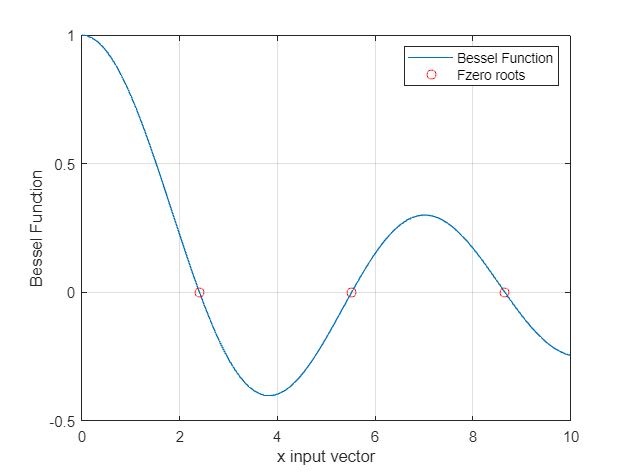

%Generate roots using fzero function
%Start timer
tic
roots = fzeroJ(0,0,10);
%End timer and save computational time
roottime = toc;

%Generate roots using bisection method
%Start timer
tic
bisectionroots = bisectionJ(0,0,10);
%End timer and save computational time
bisectiontime = toc;

%Generate roots using newton's method
%Start timer
tic
newtonroots = newtonJ(0,0,10);
%End timer and save computational time
newtontime = toc;

%Generate roots using secant method
%Start timer
tic
secantroots = secantJ(0,0,10);
%End timer and save computational time
secanttime = toc;

%Generate 100 equidistant points between 0 and 10 to plot bessel functionon
x = linspace(0,10,100);
%Evaluation bessel function with x vector input and storing in variable
%'bessel'
bessel = besselj(0,x);
y = 0;

%Create new figure
figure;
%Plot bessel function
plot(x,bessel)
hold on
%Plot fzero roots
plot(roots,y,'o','color','red')
%Add grid
grid on
%Add legend
legend('Bessel Function','Fzero roots')
%Add x and y axis labels
xlabel('x input vector')
ylabel('Bessel Function')
hold off

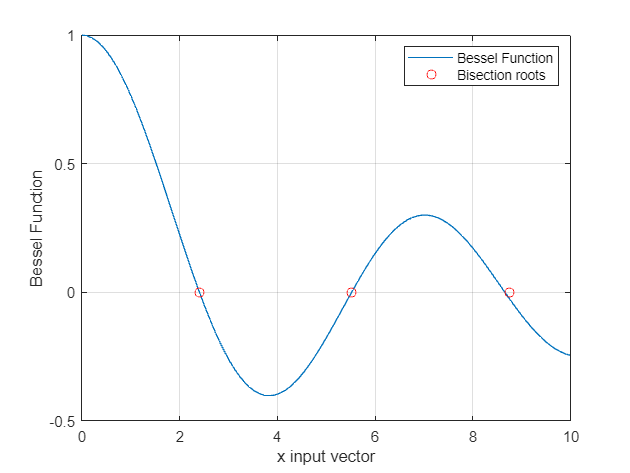

%Create new figure
figure;
%Plot bessel function
plot(x,bessel)
hold on
%Plot bisection roots
plot(bisectionroots,y,'o','color','red')
%Add grid
grid on
%Add legend
legend('Bessel Function','Bisection roots')
%Add x and y axis labels
xlabel('x input vector')
ylabel('Bessel Function')
hold off

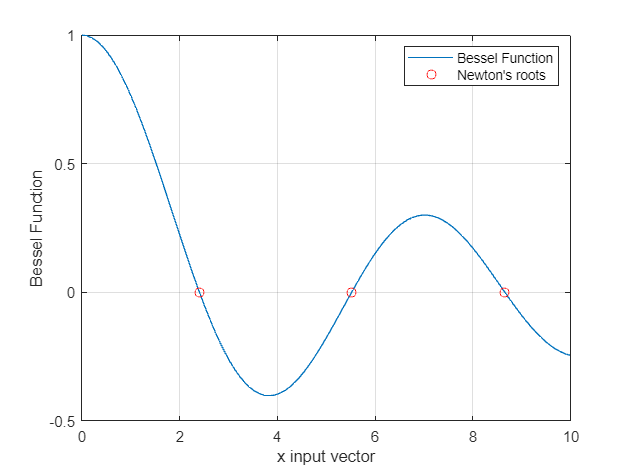


%Create new figure
figure;
%Plot bessel function
plot(x,bessel)
hold on
%Plot Newton's roots
plot(newtonroots,y,'o','color','red')
%Add grid
grid on
%Add legend
legend('Bessel Function',"Newton's roots")
%Add x and y axis labels
xlabel('x input vector')
ylabel('Bessel Function')
hold off

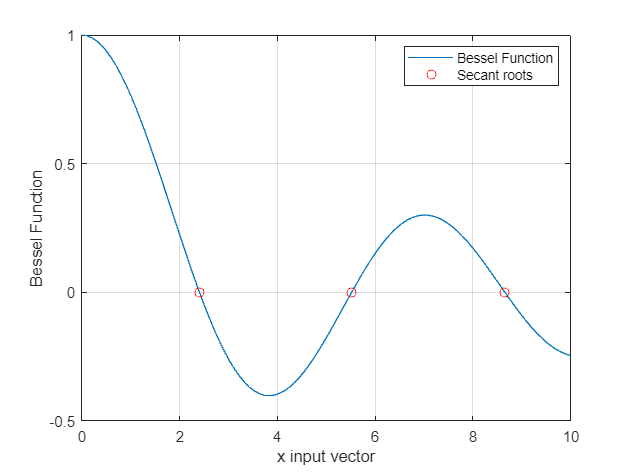


%Create new figure
figure;
%Plot bessel function
plot(x,bessel)
hold on
%Plot secant roots
plot(secantroots,y,'o','color','red')
%Add grid
grid on
%Add legend
legend('Bessel Function','Secant roots')
%Add x and y axis labels
xlabel('x input vector')
ylabel('Bessel Function')
hold off

%Outputting computational times
sprintf('Fzero took %d s to compute.',roottime)

ans = 'Fzero took 7.821240e-02 s to compute.'

sprintf('Bisection method took %d s to compute.',bisectiontime)

ans = 'Bisection method took 1.234390e-02 s to compute.'

sprintf("Newton's method took %d s to compute.",newtontime)

ans = "Newton's method took 1.243210e-02 s to compute."

sprintf('Secant method took %d s to compute.',secanttime)

ans = 'Secant method took 8.502000e-03 s to compute.'

Q3.1: The most accurate methods were Newton's method and secant method as they produced roots closest to the real roots of the bessel function produced by the fzero function. However, the bisection method was the fastest method computationally since it did not require derivatives to be evaluated. The Newton's method was computationally expensive as it took 5.86s to converge to its solutions compared to the bisection method which took 1.13s. The bisection method was the least accuate method.

### Your Functions

#### Part 1:

%M1.1
%Define local function Intpoly
%Function outputs polynomial of maximum order
%Inputs tabular data x and y

function coef = Intpoly(table)

%Define arrays x and y which contain data points
x = table(:,1);
y = table(:,2);

%N = number of data points. It is defined as a variable to avoid using
%length. 
N = length(x);

%From theory Ax = b
%Creating matrix A by multiplying matrix of ones elementwise with tabular x
%data
A = ones(N,N).*x;

%Define variable powers which is an array with integers 1:N
powers = 0:N-1;

%Use elementwise exponents to create matrix A of x values raised to powers
A= A.^powers;

%Variable coef represents 'x' in the theory. It is assigned a column vector
%of polynomial coefficients.
coef = flip((A\y)');

end

%M1.2
%Define function called LagrangePoly
%Function input = data points table as a matrix
%Input array of x values on which the polynomial will be plotted
%continously
%Function outputs evaluated polynomial
function r = LagrangePoly(table,xval)

%Define arrays x and y which contain data points
x = table(:,1)';
y = table(:,2);
p = 0;
%N = number of data points. It is defined as a variable to avoid using
%length. 
N = length(x);

%Using for loop to iterate and through lagrange basis polynomials
for i = 1:N
    for j = 1:length(xval)
        %numerator array of each basis polynomial calculated using elementwise
     %subtraction
        num = xval(j)'-x;
        %Excludes value of x - xi in numerator
        num(i)=[];
        %denominator array of basis polynomial 
        den = x(i)-x;
        %Excludes value of xi - xi in denominator
        den(i)=[];
        %Calculate lagrange basis polynomial value 
        lagrange(i,j) = y(i,:)*(prod(num)/prod(den));
        r(:,j)=sum(lagrange(:,j));
        
    end
end
end

function r = intSpline(table,xval)
    
    x = table(:,1);
    ytab = table(:,2);
    xval = xval';
    delta = 0.5;

    for i=1:length(x)-2
        b(i,:)=(ytab(i+2)-2*ytab(i+1)+ytab(i))/delta^2;
    end

    A = zeros(19);
    A(1:20:19^2)=2/3;
    A(2:20:(19^2))=1/6;
    A(20:20:19^2)=1/6;
    y = A\b;

    for i = 2:length(x)-1
        for j = 1:length(xval)
            r(j,i)=(y(:,i)/6)*(((x(i+1)-xval(j))^3)/(x(i+1)-x(i))-(x(i+1)-x(i))*(x(i+1)-xval(j))+(y(:,i+1)/6)*((((xval(j)-x(i))^3)/(x(i+1)-x(i))-(x(i+1)-x(i))*(xval(j)-x(i)))+ytab(i)*((x(i+1)-xval(j))/(x(i+1)-x(i)))+ytab(i+1)*((xval(j)-(i))/(x(i+1)-x(i)))));
        end
    end
end


#### Part 2:

%Define function trapzJ1 for trapezium rule integration.
%Input x vector and N number of points used in integration.
%Function outputs'J1x' as vector of the evaluated bessel function.
function J1x = trapzJ1(x,N)

    %Define variable 'a' as the lower integral limit.
    a = 0;
    %Define variable 'b' as the upper integral limit.
    b = pi;

    %Define vector t as points to be used in trapezium rule.
    t = linspace(a,b,N);
    %Preallocating matrix y to improve efficiency.
    y=zeros(length(x),length(t));
    %Preallocating vector J1x to improve efficiency.
    J1x = zeros(1,length(x));

    %Use for loop to evaluate the integral at every input x point
    for i=1:length(x)
            %Define matrix y to store integrand values each time a new value of x
            %is used.
            y(i,:) = cos(t-x(i)*sin(t));
            %Store integral solutions into output variable 'J1x'
            %Trapezium rule evaluated using inbuilt 'trapz' function.
            J1x(i)=(1/pi)*trapz(t,y(i,:));
    %End for loop        
    end
%End function 'trapzJ1'    
end

%Define function simpsonJ1.
%Input x vector and N number of points used in integration.
%Function outputs'J1x' as vector of the evaluated bessel function using Simpson's 1/3 rule. 
function J1x = simpsonJ1(x,N)

    %Define variable 'a' as the lower integral limit.
    a = 0;
    %Define variable 'b' as the upper integral limit.
    b = pi;
    
    %Define vector t as points to be used in trapezium rule.
    t = linspace(a,b,N);
    %Define variable 'h' as the interval width.
    h = (b-a)/N;
    
    %Create nested function 'f' to generate integrand
    %Function inputs x and tau values
    function integrand = f(x,t)
            %Evaluating bessel's first order integrand
            integrand= cos(t-x*sin(t));
    end
    
    %Using for loop that iterates through each element in vector 'x'
    for i = 1:length(x)
        %Using nested for loop to iterate through each tau 't' element
        for j = 1:length(t)
            %computes solutions to the integrand at each odd position in
            %'t' %vector.
            %example. f(x(i),t(3,5,7...))
            oddf = f(x(i),t(:,3:2:end-1));
            %computes solutions to the integrand at each even position in
            %'t' vector.
            %example. f(x(i),t(2,4,6...))
            evenf = f(x(i),t(:,2:2:end-2));
            J1x(i) = (1/pi)*(h/3)*(f(x(i),t(1))+sum(2*oddf)+sum(4*evenf)+f(x(i),t(end)));
        end
    end
end


%Define function gaussJ1.
%Input x vector and N number of points used in integration.
%Function outputs'J1x' as vector of the evaluated bessel function using Gaussian Legendre Quadrature. 
function J1x = gaussJ1(x,N)

    %Define function 'integ' to calculate integrand value.
    %input specific x and tau values
    function res = integ(x,t)
        %Bessel's first order integrand.
        res = cos(t-x*sin(t));
    end
    
    %Define array 'polycoeff' containing coefficients of the expression x^2
    %-1
    polcoeff = [1 0 -1];
    %Initialise value of variable 'pol'
    pol = 1;
    %Define for loop to iterate for N times.
    for i = 1:N
        %Each increment in 'i' increases the power of the polynomial
        %conv function generates vector of polynomial coefficients.
        pol = conv(pol,polcoeff);
    end
   
    %Define Variable 'der' to contain initial polynomial 'pol'
    der = pol;
    %Create for loop to differentiate polynomial 'N'times.
    for i = 1:N
        %Variable 'der' stores derivative coefficients.
        der = polyder(der);
    end
    
    %Variable ni stores quadtrature points as an array.
    %Function 'roots' used to calculate roots of legendre polynomial.
    ni = roots((1/(2^N*factorial(N)))*der)';

    %for loop used to calculate quadrature weights
    %Loop iterates through all quadrature points.
    for i = 1:length(ni)
        %Variable 'wi' stores the quadrature weights.
        %Quadrature weight equation defined from theory.
        %Function polyval and polyder used to evaluate polynomial at each
        %quadrature point
        wi(i) = (2/(1-ni(i)^2))*((polyval(polyder((1/(2^N*factorial(N)))*der),ni(i)))^(-2));
    end
    
    %For loop used to evaluate integrand for each x value
    for i = 1:length(x)
        %Nested for loop used to evaluate integrand at each quadrature
        %point and weight
        for j = 1:N
            %Matrix 'integrand' stores all integrand values'
            %Integral limits changed by using '(pi/2+(pi/2*ni) instead of
            %ni.
            integrand(:,j) = wi(j)*integ(x,(pi/2) + (pi/2)*ni(j));
        end
        %Output variable J1x stores the sum of integrands for each x value.
        J1x(i)=sum(integrand(i,:));
    end
    %Integral multiplied by '1/2' to compensate for limit change
    %(1/pi)*(pi/2)=(1/2)
    J1x = J1x/2;
%End function
end 

#### Part 3:

%Define function that uses inbuilt fzero function to calculate roots
%Inputs bessel function order and search interval limits
function roots = fzeroJ(N,a,b)
%Defining bessel function
J = @(x) besselj(N,x);
%Creating search interval vector using search limits
interval = linspace(a,b,10);
%Initialising output variable 
roots=[];
%For loop that iterartes through search interval
for i = 1:length(interval)
    %Checking if root exists by looking for sign change
    if J(i)*J(i+1)<0
        %If root exists, fzero function used to evaluate root and store it
        %in output.
        roots(end+1)=fzero(J,interval(i));
    end
end
end

%Define function that uses bisection method to calculate roots
%Inputs bessel function order and search interval limits
function roots =bisectionJ(N,a,b)
    %Initialising output variable 
    roots = [];
    %Defining bessel function
    J = @(x) besselj(N,x);
    %Creating search interval vector using search limits
    interval = linspace(a,b,9);
    %For loop that iterartes through search interval
    for i = 1:length(interval)-1
        %Checking if root exists by looking for sign change
        if J(i)*J(i+1)<0
            %Initialise variable delta which stores difference between
            %consecutive root estimations
            delta = 1;
            %Initial limits for bisection produced
            %From theory in handout these are a and b
            x1 = interval(i);
            x2 = interval(i+1);
            %Temporary variable initialised
            temp = [];
            %While loop iterates until sufficient precision is achieved
            while delta>0.000001
                %Finding midpoint 'c' using bisection
                c = (x1+x2)/2;
                 %Evaluating c and assigning it to either the lower limit or upper limit
                 %depending on sign
                if J(c)*J(i)<0
                    x2 = c;
                    %Updating precision variable 'delta'
                    delta = abs(c-x1);
                else 
                    delta = abs(c-x1);
                    x1 =c;
                end
            %Once root is found it is stored in temporary variable    
            temp(i)=c;
            end
            %Adding root to output variable
            roots(end+1)=temp(i);
        end
    end
end



%Define function that uses Newton's method to calculate roots
%Inputs bessel function order and search interval limits
function roots = newtonJ(N,a,b)
    %Creating search interval vector using search limits
    interval = linspace(a,b,11);
    %Initialising output variable
    roots = [];
    %Defining bessel function
    J = @(x) besselj(N,x);
    %For loop that iterartes through search interval
    for i = 1:length(interval)
        %Checking if root exists by looking for sign change
        if J(i)*J(i+1)<0
            %x1 assigned initial value
            x1 = interval(i);
            %Initialise variable delta which stores difference between
            %consecutive root estimations
            delta = 1;
            %While loop iterates until sufficient precision is achieved
            while abs(delta)>0.000001
                %Implementation of Newton's method from theory in handout
                x2 = x1 - J(x1)/(0.5*(J(i-1)-J(i+1)));
                %Updating precision variable 'delta'
                delta = x2 - x1;
                %Value of root being updated
                x1 = x2;
            end
            %Using if statement to ensure roots are within search interval
            if x1>=a &x1 <=b
                %Adding roots to output variable if they lie within search
                %interval
                roots(end+1)=x1;
            end
        end
    end
end

%Define function that uses Secant method to calculate roots
%Inputs bessel function order and search interval limits
function roots = secantJ(N,a,b)
    %Creating search interval vector using search limits
    interval = linspace(a,b,11);
    %Initialising output variable
    roots = [];
    %Defining bessel function
    J = @(x) besselj(N,x);
    %For loop that iterartes through search interval
    for i = 2:length(interval)
        %Checking if root exists by looking for sign change
        if J(i)*J(i+1)<0
            %x0 and x1 assigned initial values according to theory
            x1 = interval(i);
            x0 = interval(i-1);
            %Initialise variable delta which stores difference between
            %consecutive root estimations
            delta = 1;
            %While loop iterates until sufficient precision is achieved
            while abs(delta)>0.000001
                %Implementation of Secant method from theory in handout
                x2 = x1 - J(x1)*(x1-x0)/(J(x1)-J(x0));
                %Updating precision variable 'delta'
                delta = x2 - x1;
                %Values of root being updated
                x0 = x1;
                x1 = x2;
            end
            %Using if statement to ensure roots are within search interval
            if x1>=a &&x1 <=b
                %Adding roots to output variable if they lie within search
                %interval
                roots(end+1)=x1;
            end
        end
    end
end